# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet

c0_1 = 0.001;  
c0_2 = 0.023;

c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0014;
c4 = 0.0077;

tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 0;

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;

## **2) **

**Solutions**

[~,~,~,~,H0_2,~,conds_Sol_2,...
    ~,~,output_2,history_2,History_2,h_Sol_2,H_Sol_2]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c0_1,c0_2,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          50.5894         
     1            3          49.8626         initial simplex
     2            5          35.2964         expand
     3            7          21.8721         expand
     4            9          7.18169         reflect
     5           11            3.955         reflect
     6           13            3.955         contract outside
     7           15           3.5053         contract inside
     8           17           3.5053         contract inside
     9           19           3.5053         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



[tSpan,D1,D2,X,H0,myObjective_Possition,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c1,c2,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          35.5572         
     1            3          29.0734         initial simplex
     2            5          16.9469         expand
     3            7          7.08457         expand
     4            9          6.59107         reflect
     5           11          6.59107         contract outside
     6           13           3.5741         contract outside
     7           15           3.5226         contract inside
     8           17          2.68639         contract inside
     9           18          2.68639         reflect
    10           20          2.68639         contract inside
    11           22          2.60711         contract inside
    12           24          2.60711         contract inside
    13           26          2.35338         reflect
    14           28          2.35338         contract inside
    15           30           2.3271         reflect
    16           32           

[~,~,~,~,H0_1,~,conds_Sol_1,...
    ~,~,output_1,history_1,History_1,h_Sol_1,H_Sol_1]...
    = Disjoining(tfinal,dx,X,k,y0,N,A,c3,c4,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          48.3252         
     1            3           45.441         initial simplex
     2            5          39.2328         expand
     3            7          31.3419         expand
     4            9          14.0876         expand
     5           11          5.63299         reflect
     6           13          5.63299         contract inside
     7           14          5.63299         reflect
     8           16          5.63299         contract inside
     9           18           5.0391         contract inside
    10           20          1.65353         contract inside
    11           21          1.65353         reflect
    12           23          1.65353         contract inside
    13           25          1.65353         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criter

**Figures**

var = [A;N;k;y0]; 

h = hFinal(history(3,:),X,var,D1,D2,tSpan);
H = deval(h,tfinal); 

h_1 = hFinal(history_1(5,:),X,var,D1,D2,tSpan);
H_1 = deval(h_1,tfinal);   

h_2 = hFinal1(history_2(5,:),X,var,D1,D2,tSpan);
H_2 = deval(h_2,tfinal);   

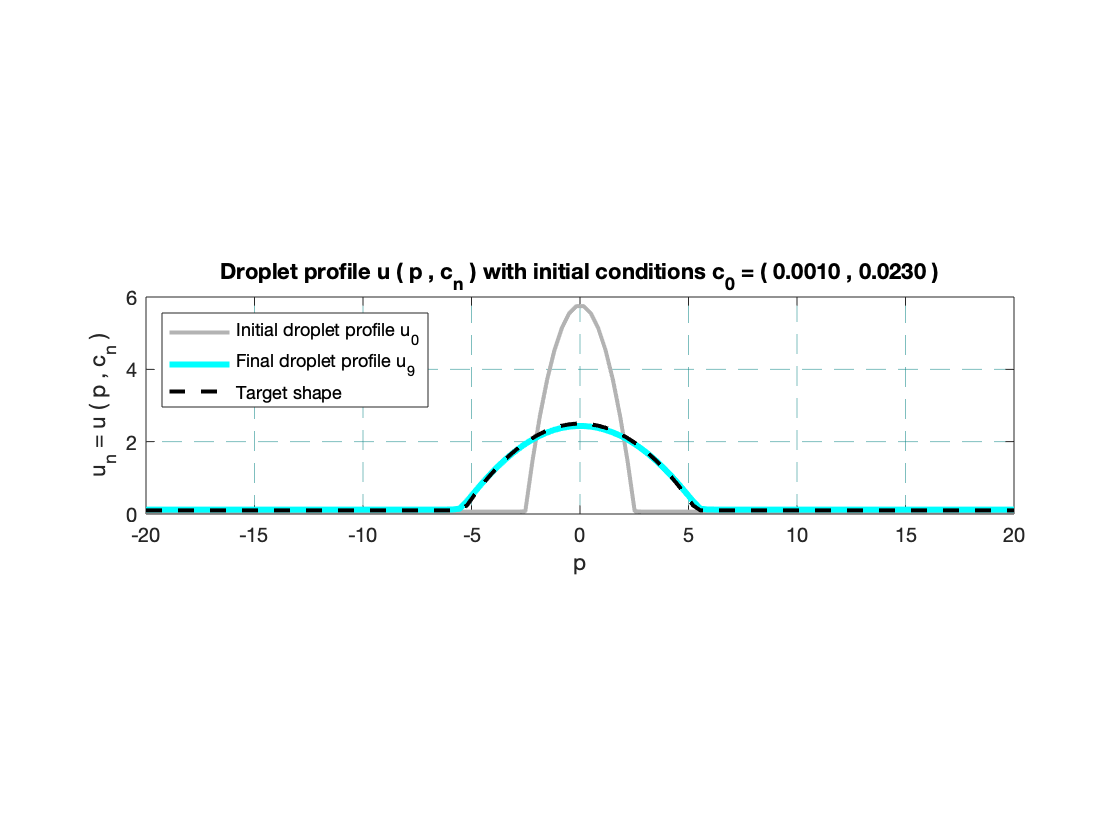

figure;
hold on
box on
pbaspect([4 1 1]);
plot(X,H0_2,'-','Color',[0.7 0.7 0.7],'linewidth',2);
%plot(X,H_2,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2,'c-','linewidth',3);
plot(X,h_target,'k--','linewidth',2);
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{9}',...
    'Target shape',...
    'Location','northwest');
title('Droplet profile u ( p , c_n ) with initial conditions c_0 = ( 0.0010 , 0.0230 )');
xlabel('p')
ylabel('u_n = u ( p , c_n )')
xlim([-20 20]);
ylim([0 6]);
grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
hold off

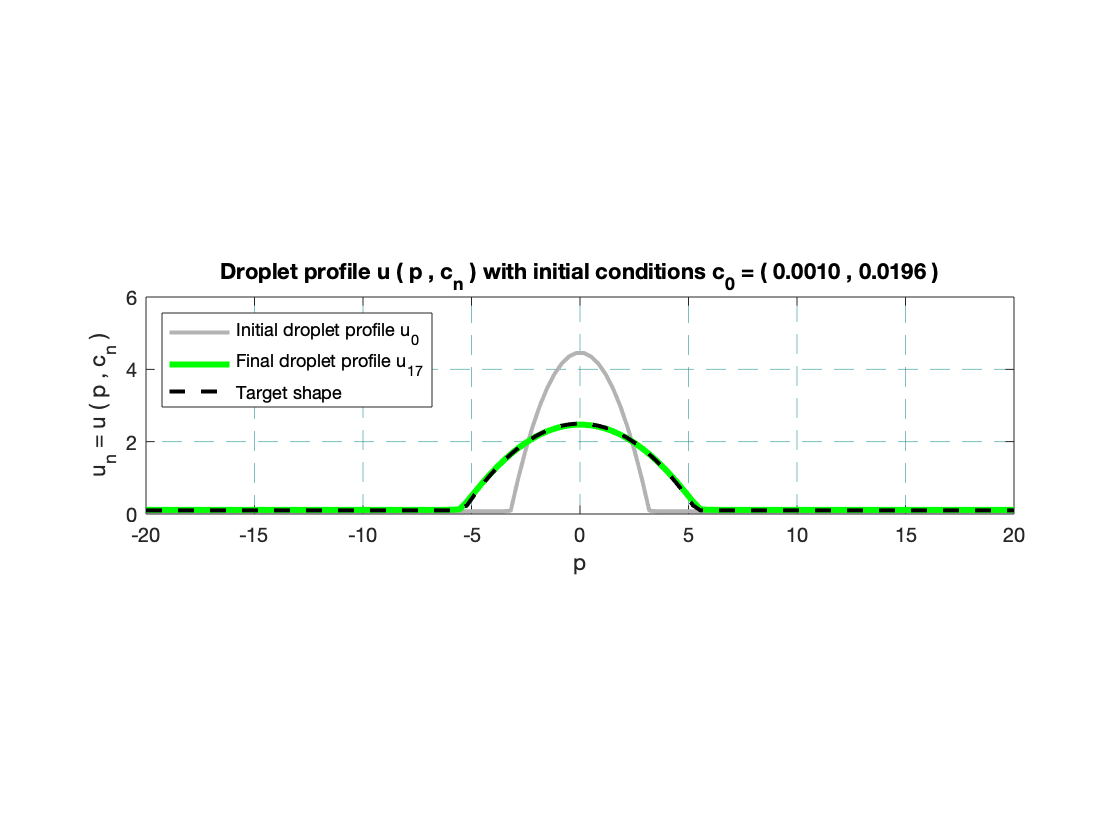


figure;
hold on
box on
pbaspect([4 1 1]);
plot(X,H0,'-','Color',[0.7 0.7 0.7],'linewidth',2);
%plot(X,H,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol,'g-','linewidth',3);
plot(X,h_target,'k--','linewidth',2);
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{17}',...
    'Target shape',...
    'Location','northwest');
title('Droplet profile u ( p , c_n ) with initial conditions c_0 = ( 0.0010 , 0.0196 )');
xlabel('p')
ylabel('u_n = u ( p , c_n )')
xlim([-20 20]);
ylim([0 6]);
grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
hold off

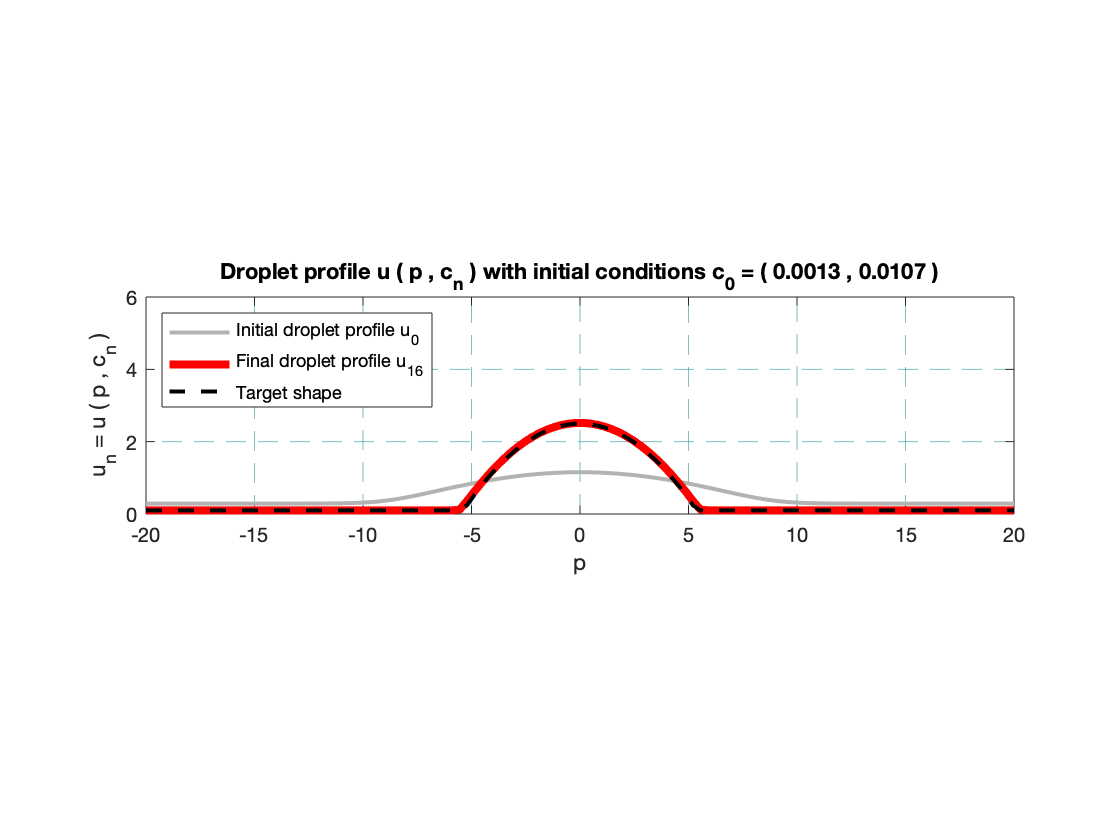


figure;
hold on
box on
pbaspect([4 1 1]);
plot(X,H0_1,'-','Color',[0.7 0.7 0.7],'linewidth',2);
%plot(X,H_1,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1,'r-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{16}',...
    'Target shape',...
    'Location','northwest');
title('Droplet profile u ( p , c_n ) with initial conditions c_0 = ( 0.0013 , 0.0107 )');
xlabel('p')
ylabel('u_n = u ( p , c_n )')
xlim([-20 20]);
ylim([0 6]);
grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
hold off

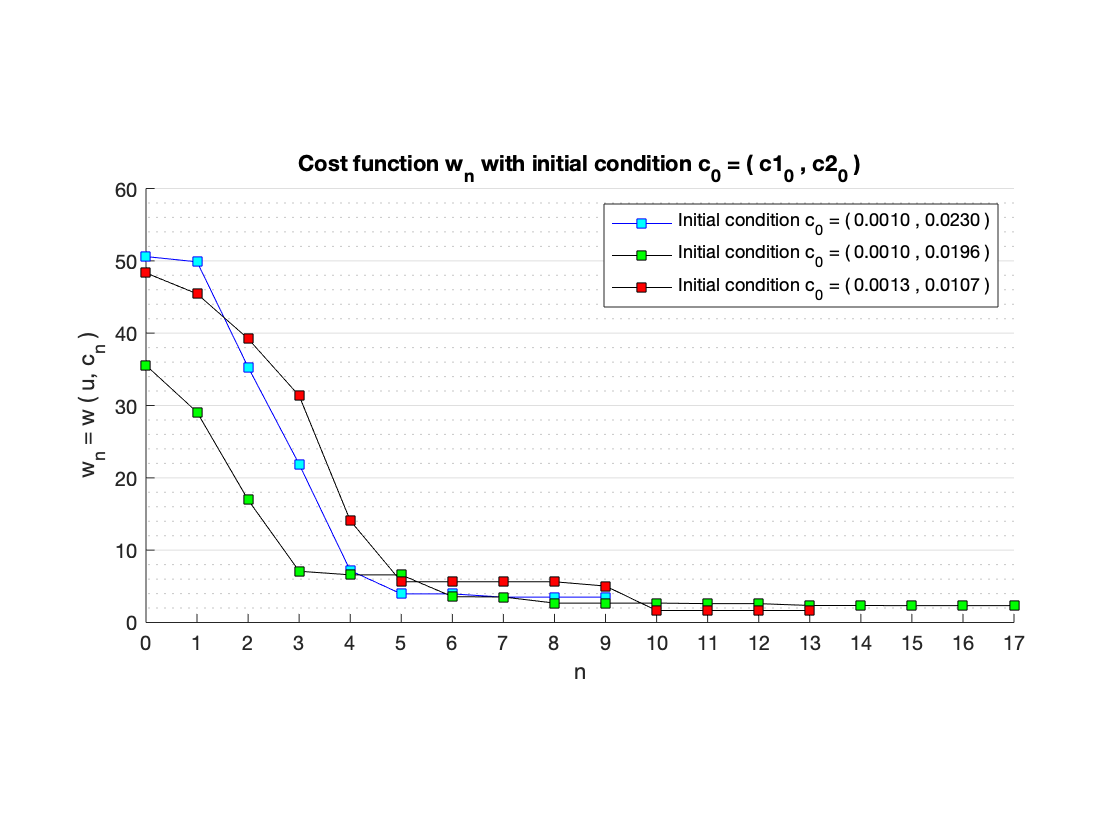

n = size(history);
n = n(1);
C1 = history(:,1);
C2 = history(:,2);
C3 = history_1(:,1);
C4 = history_1(:,2);
lineHi = 0:1:n-1;

figure;
hold on
plot(0:9,History_2,'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c');
plot(0:17,History,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g');
plot(0:13,History_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r');
pbaspect([2 1 1]);
box off
title('Cost function w_n with initial condition c_0 = ( c1_0 , c2_0 )');
ylabel('w_n = w ( u, c_n )');
xlabel('n');
legend('Initial condition c_0 = ( 0.0010 , 0.0230 )','Initial condition c_0 = ( 0.0010 , 0.0196 )','Initial condition c_0 = ( 0.0013 , 0.0107 )');
set(gca,'xtick',0:1:100);
set(gca,'ytick',0:10:500);
xlim([0 17]);
ylim([0 60]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
hold off

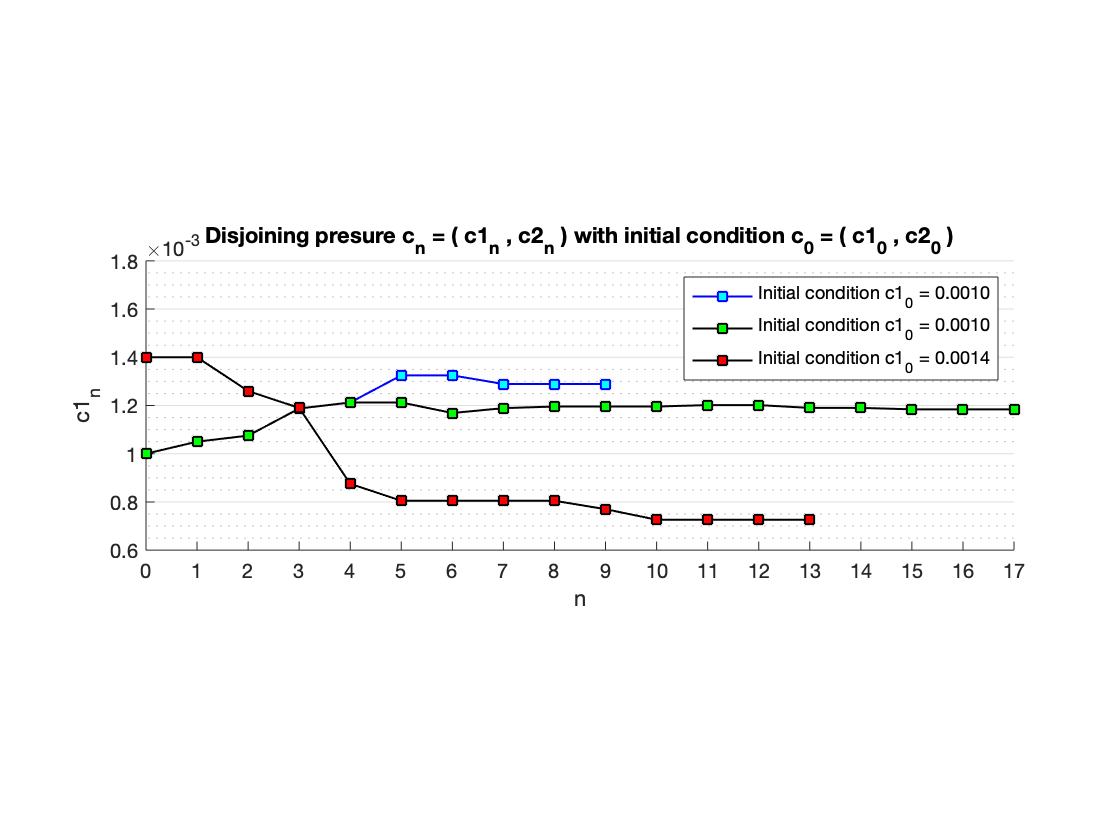


figure;
hold on
plot(0:9,history_2(:,1),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
plot(0:17,C1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:13,C3,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
box off
ylabel('c1_n');
xlabel('n');
title('Disjoining presure c_n = ( c1_n , c2_n ) with initial condition c_0 = ( c1_0 , c2_0 )');
legend('Initial condition c1_0 = 0.0010',...
    'Initial condition c1_0 = 0.0010',...
    'Initial condition c1_0 = 0.0014',...
    'Location','northeast');
set(gca,'xtick',0:1:100);
xlim([0 17]);
ylim([0.0006 0.0018]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([3 1 1]);
hold off

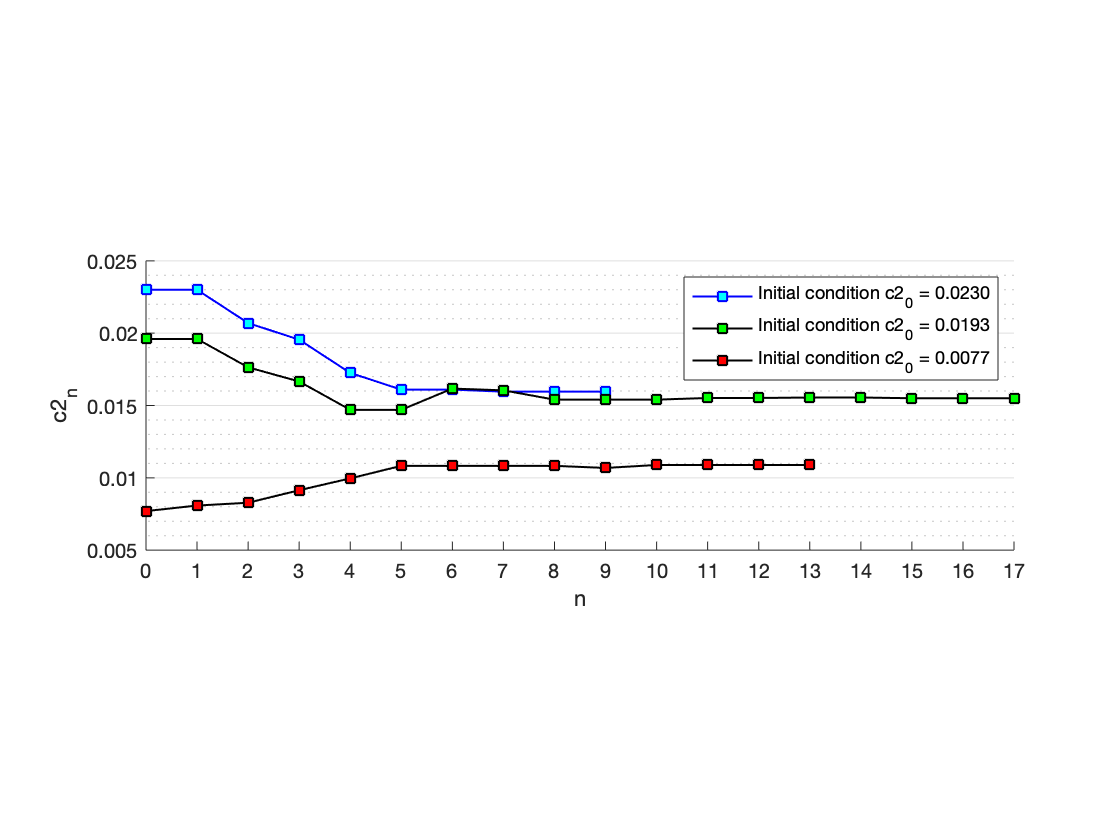


figure;
hold on
plot(0:9,history_2(:,2),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
plot(0:17,C2,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:13,C4,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
box off
ylabel('c2_n');
xlabel('n');
legend('Initial condition c2_0 = 0.0230',...
    'Initial condition c2_0 = 0.0193',...
    'Initial condition c2_0 = 0.0077',...
    'Location','northeast');
set(gca,'xtick',0:1:100);
xlim([0 17]);
ylim([.005 .025]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([3 1 1]);
hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis